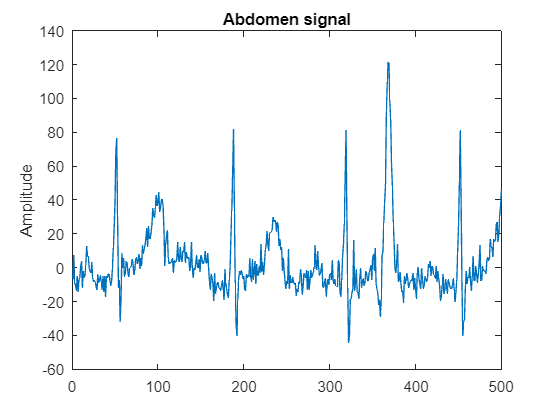

%Testing values

N = 3; % order, odd-number 3
delta = 0.000002; % small number 0.000002

load('Parent_Fetus_ECGs.mat');

figure(1)
plot(S_abdomen(2001:2500)); drawnow;
title('Abdomen signal')
ylabel('Amplitude')

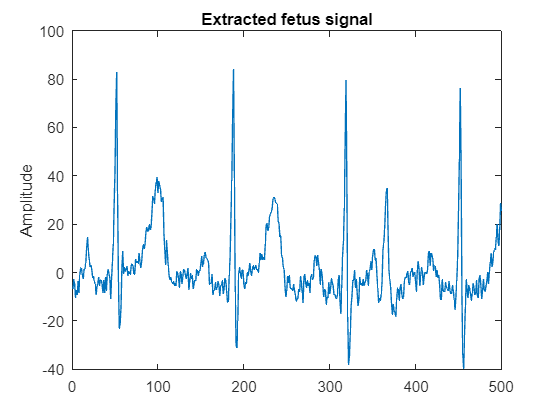

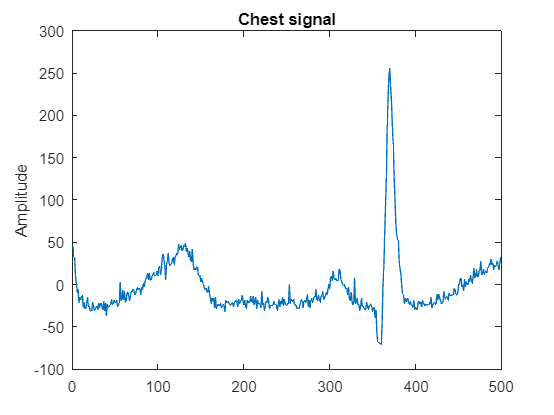

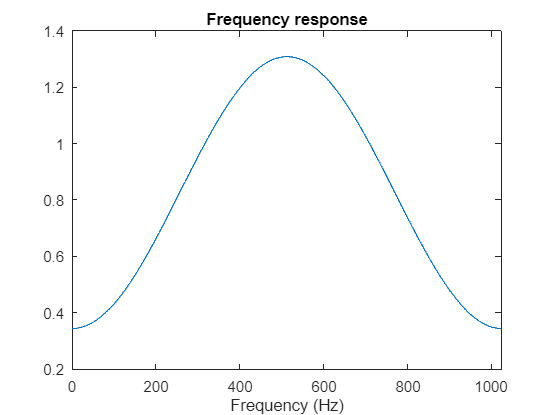


H = zeros(1, N); % start value
for i = 1:7
    [e, H] = adaptive(S_chest, S_abdomen, delta, N, H);

    figure(2)
    plot(e(2000:2499)); % a part of the fetus%s ECG
    title('Extracted fetus signal')
    ylabel('Amplitude')
    figure(3)
    plot(S_chest(2000:2499)) % mother's ECG in the same range
    title('Chest signal')
    ylabel('Amplitude')

    figure(4)
    plot(abs(fft(H, 1024))); drawnow; % filter%s freq resp
    xlim([0,1024])
    title('Frequency response')
    xlabel("Frequency (Hz)")
end